clear all; clc;
digits(300);
addpath ./embedded
addpath ./mifiltertools
addpath ./utils
format LONGE

**Parámetros de diseño**

fm=150000;             % Hz,  Frecuencia de Muestreo
                             
%---------------------------------|--------------------------------------
                                f0=10000;
BMAX=2*f0;
%-------------------|xxxxxxxxxxxxxxxxxxxxxxxxxxx|----------------------------
                 B1=2000;  

%--------------------yyy|xxxxxxxxxxxxxxxxxxx|yyyy----------------------------       
            B2=865;  Ap=0.5 ;                 
            
%xxxxxxxx|----------------------------------------------------|xxxxxxxxxx                                                          
     B3=2652;  As=10 ;


w0=2*pi*f0;
B= 2*pi*B1;
Bp=2*pi*B2;
Bs=2*pi*B3;

**Diseño del filtro**

- Encontrar las frecuencias de borde

syms w;

%  frecuencia de corte
[s1]=vpasolve(w^2+B*w-w0^2==0,w);
f1=s1(2)/2/pi;
f2=(B+f1*2*pi)/2/pi;

%  frecuencias en la banda de paso
[s3]=vpasolve(w^2+Bp*w-w0^2==0,w);
f3=s3(2)/2/pi;
f4=(Bp+f3*2*pi)/2/pi;

% frecuencias en la banda de rechazo
[s5]=vpasolve(w^2+Bs*w-w0^2==0,w);
f5=s5(2)/2/pi;
f6=(Bs+f5*2*pi)/2/pi;

- Transformar las caracteristicas de frecuencia de paso bajo a paso bajo normalizado

Fc=1;
Fp=(f4-f3)/(f2-f1);
Fs=(f6-f5)/(f2-f1);

- Cálculo del Orden del filtro:

N=mi_butter_orden_lp(Fp, Ap, Fs, As)

$$N = 12$$

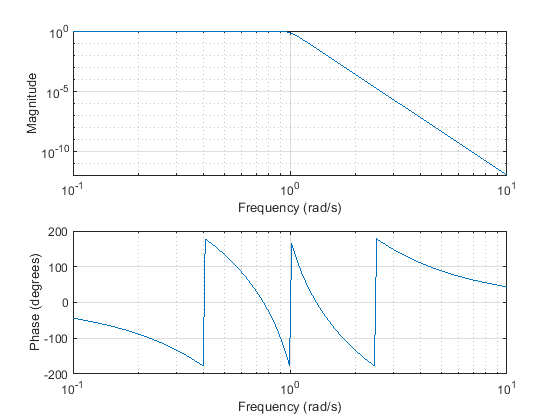

%[Bs,As]=butter(N, Fc*2*pi, 'low','s');
[BS,AS]=mi_butter(N);
freqs(BS,AS);

- Transformación en frecuencia

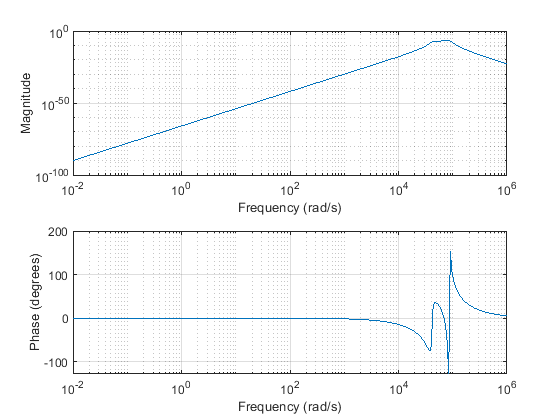

[Bs, As] = mi_lp2bp(BS,AS, w0, B);
freqs(Bs, As);

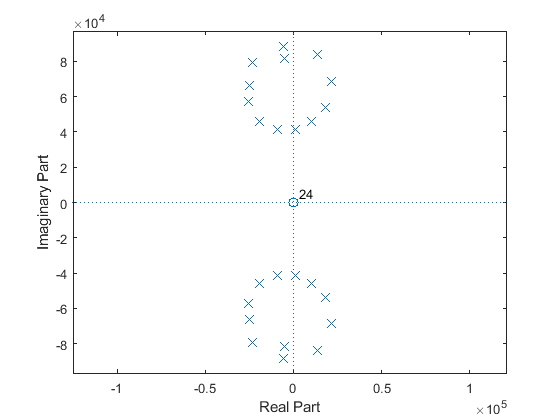

Np=max(length(Bs),length(As));
figure, zplane( [Bs zeros(1, Np- length(Bs)+1) ], [ As zeros(1, Np- length(As)+1)] );

**Transformación bilinear - matlab.**

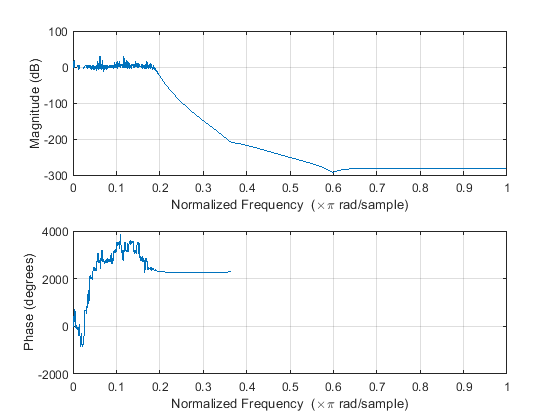

mapeo="bilineal(matlab)";

switch mapeo
    case "integracion"
        [Bz, Az]=mi_integral(Bs, As, fm);
    case "invariante al impulso"
        [Bz, Az]=mi_impinvar(Bs, As, fm);
    case "invariante(matlab)"
        [Bz, Az]=impinvar(Bs, As, fm);
    case "bilineal"
        [Bz, Az]=mi_bilinear(Bs, As, fm, f0/fm);
    case "bilineal(matlab)"
        [Bz, Az]=bilinear(Bs, As, fm, f0/fm);        
end
m=max( abs([ Bz, Az ]) );
Bz=Bz/m;
Az=Az/m;
Bz=Bz/Az(1);
Az=Az/Az(1);
freqz(Bz,Az,2048);

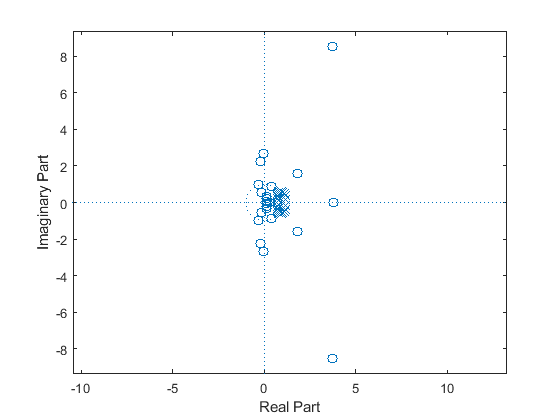

figure;
Np=max(length(Bz),length(Az));
zplane( [Bz zeros(1,  Np- length(Bz)+1) ], [Az zeros(1, Np- length(Az)+1) ] );

**Generación de la linea para inicializar el callback de simulink**

PRECISION_STM32=6;
to_simulink(Bz, Az, double(N), fm, PRECISION_STM32, 'Pasa Banda', mapeo)

ans =     '	%Filtro Pasa Banda - bilineal(matlab) 
     	%Orden: 12
     	%Frecuencia de Muestreo: 150000 (Hz)
     	Fm=150000;
     	ORDEN=12;
     	coef_x= [0,-1.42109e-14,2.27374e-13,-2.72848e-12,1.72804e-11, ...
     			-7.63976e-11,2.76486e-10,-7.85803e-10,1.86265e-09,-3.60887e-09, ...
     			6.0536e-09,-7.91624e-09,9.31323e-09-9.0804e-097.79983e-09 ...
     			-5.58794e-093.31784e-09-1.71713e-097.34872e-10-2.58296e-10 ...
     			7.18501e-11-1.50067e-112.27374e-12-2.18492e-131.02141e-14 ...
     			];
     	coef_y= [-1,21.4201,-221.691,1475.06,-7082.43, ...
     			26112.5,-76805.9,184844,-370387,625535, ...
     			-897975,1.10181e+06,-1.1592e+061.04679e+06-810519 ...
     			536414-301755143072-56479.818243.1 ...
     			-4700.92930.165-132.81612.1921-0.540769 ...
     			];'


**Generación de la linea para la fpga**

Nbits=64;
Qbits=32;
to_fpga(Bz, Az, N, fm, Qbits,Nbits, 'Pasa Banda', mapeo)

ans =     '//Filtro Pasa Banda - bilineal(matlab)
     //Orden: 12
     //Frecuencia de Muestreo: 150000 (Hz)
     assign dx0=64'0x0000000000000000;assign dx1=64'0x0000000000000000;assign dx2=64'0x0000000000000001;assign dx3=64'0x0000000000000000; 
     			assign dx4=64'0x0000000000000001;assign dx5=64'0x0000000000000000;assign dx6=64'0x0000000000000002;assign dx7=64'0xFFFFFFFFFFFFFFFD; 
     			assign dx8=64'0x0000000000000008;assign dx9=64'0xFFFFFFFFFFFFFFF1;assign dx10=64'0x000000000000001A;assign dx11=64'0xFFFFFFFFFFFFFFDE; 
     			assign dx12=64'0x0000000000000028;assign dx13=64'0xFFFFFFFFFFFFFFD9;assign dx14=64'0x0000000000000022;assign dx15=64'0xFFFFFFFFFFFFFFE8; 
     			assign dx16=64'0x000000000000000F;assign dx17=64'0xFFFFFFFFFFFFFFF9;assign dx18=64'0x0000000000000004;assign dx19=64'0xFFFFFFFFFFFFFFFF; 
     			assign dx20=64'0x0000000000000001;assign dx21=64'0x0000000000000000;assign dx22=64'0x0000000000000001;assign dx23=64'0x0000000000000000; 
     			assign dx24=64'0x00